% Load MNIST dataset
digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', 'nndatasets', 'DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders', true, 'LabelSource', 'foldernames');
% Normalize the images
imds.ReadFcn = @(x) double(imread(x))/255;

% Split into training and validation data
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7, 'randomize');

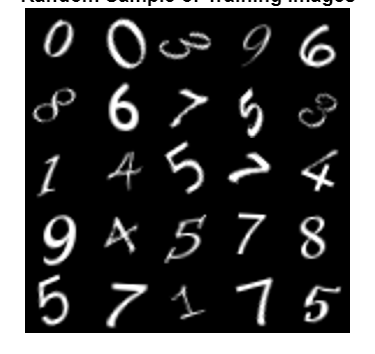

% Display a random sample of 9 images from the training set
figure;
perm = randperm(numel(imdsTrain.Files), 9);
subset = imageDatastore(imdsTrain.Files(perm));
montage(subset.Files, 'Size', [3 3]); % 3x3 because we want to display 9 images
title('Random Sample of Training Images');

layers = [
    imageInputLayer([28 28 1]) % Input layer - for 28x28x1 image size

    convolution2dLayer(3, 8, 'Padding', 'same') % Convolutional layer with 8 filters of size 3x3
    reluLayer % Activation layer using ReLU
    
    maxPooling2dLayer(2, 'Stride', 2) % Max pooling layer with a 2x2 window and stride of 2

    convolution2dLayer(3, 16, 'Padding', 'same') % Another convolutional layer
    reluLayer % Activation layer using ReLU
    
    maxPooling2dLayer(2, 'Stride', 2) % Max pooling layer

    fullyConnectedLayer(10) % Fully connected layer with 10 outputs
    softmaxLayer % Softmax activation layer
    classificationLayer % Classification layer
];

options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 4, ...
    'MiniBatchSize', 64, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsValidation, ...
    'ValidationFrequency', 30, ...
    'Verbose', false, ...
    'Plots', 'training-progress');

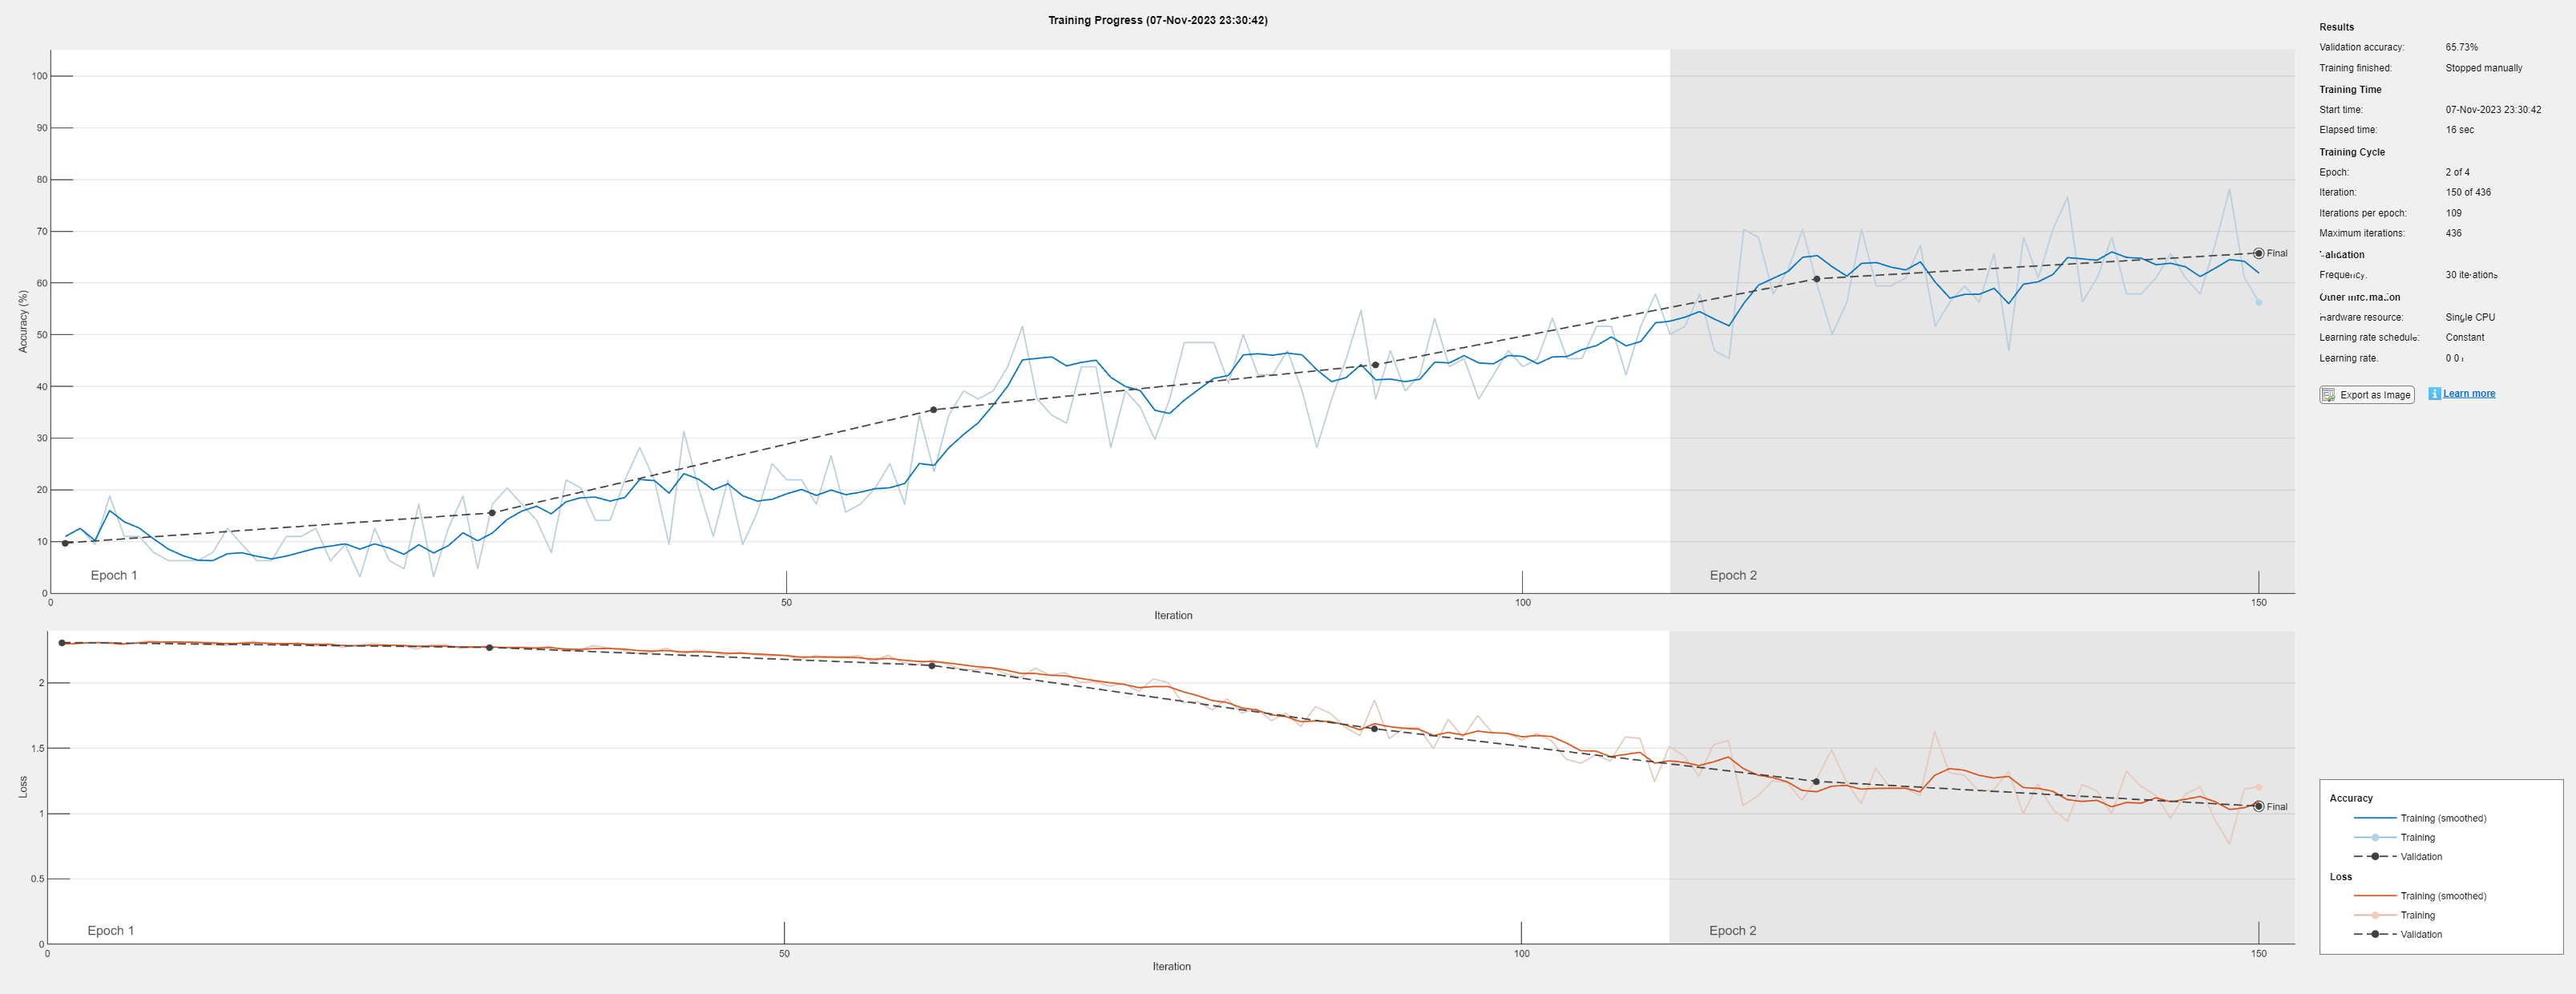

Unrecognized function or variable 'dd'.

net = trainNetwork(imdsTrain, layers, options);